# Niryo Ned2 Real Robot

**Important: **add Ned2 ip address to your hosts file (requires Admin priviledges) 

- Windows`: C:\Windows\System32\drivers\etc\hosts`

- Linux/Mac: `/etc/hosts`

For example, if you are using Niryo Hotspot, add the following line

If you are using Ethernet or WiFi, add the following line

Connect to Ned2

 
ned = Ned2('ned2');

Calibrate Joints

 
ned.JointCalibration("ForceCalibration",false);

Show the robot

ned.show();

**Home configuration**

The home configuration is the one in which all the joints are 0.

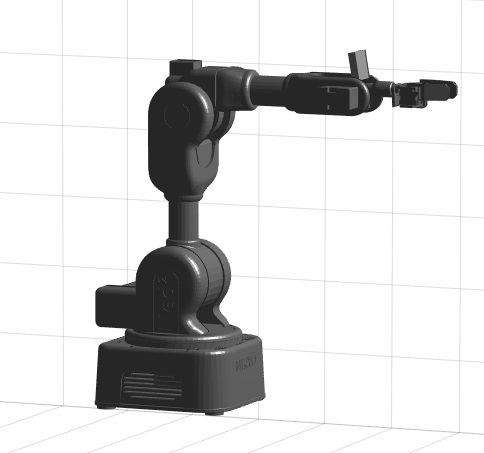

 
ned.goHome();

### Control joints / Forward Kinematics

Use the sliders to control the robot joints.

j1 = 0; % Base
j2 =0; % Shoulder
j3 =0; % Elbow
j4 =0; % Forearm
j5 =0; % Wrist
j6 =0; % Hand
ned.SetPose([j1 j2 j3 j4 j5 j6]);

T = getTransform(ned.RigidBodyTree,[ned.CurrentConfiguration ned.GripperConfiguration],'end_effector','base_link')

### Trajectory Planning

Use `PlanTrajectory` to plan a trajectory that follows multiple waypoints. 

 
waypoints = [ned.HomeConfiguration;
             % Add your waypoints
            -0.0601    0.1570   -0.7522    0.0062   -0.9374   -0.0275;
            -0.0053    0.6100    0.4613    0.0737   -0.0538   -0.0475;
             ned.HomeConfiguration];

ned.plotTraj = true;
ned.clearFigure;
ned.goHome();

duration = 5;
ned.PlanTrajectory(waypoints,duration,'minjerkpolytraj');

### Inverse Kinematics

Use `Move `to plan a trajectory to a XYZ point in space (X = front, Y = left, Z, up) with respect to the center of the base.

 
ned.goHome()
XYZ = [0.3, 0, 0.1];
RPY = [0,  pi/2, 0];
duration = 2;

ned.Move(XYZ,RPY,duration);
getTransform(ned.RigidBodyTree, ...
            [ned.CurrentConfiguration ned.GripperConfiguration], ...
            'end_effector','base_link')

### Camera Feedback

Get an image from the camera

 
I = ned.snapshot();
imshow(I)

### **Gripper**

 
ned.openGripper();

 
ned.closeGripper();

**Idle configuration**

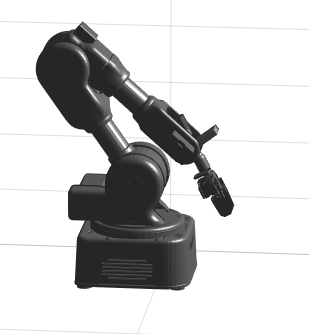

ned.goIdle();

Copyright 2024-2025 The MathWorks, Inc.